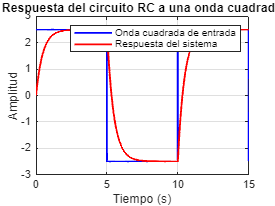

% Definir parámetros del circuito
R = 10000; % Resistencia en ohmios
C = 0.000047; % Capacitancia en faradios

% Definir el sistema de circuito RC en el dominio de Laplace
num = [1];
den = [R*C, 1];
sys = tf(num, den);

% Definir la forma de onda cuadrada
t = 0:0.01:15; % Vector de tiempo de 0 a 50 segundos
square_wave = 2.5 * square(2*pi*0.1*t); % Onda cuadrada con amplitud de 2.5 y periodo de 10 segundos

% Simular la respuesta del sistema a la onda cuadrada
[y, t_sim] = lsim(sys, square_wave, t);

% Graficar la forma de onda cuadrada y la respuesta del sistema
figure;
plot(t, square_wave, 'b', t_sim, y, 'r', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Respuesta del circuito RC a una onda cuadrada');
legend('Onda cuadrada de entrada', 'Respuesta del sistema');
grid on;